clear;

% MAKE SURE THAT IF YOU ADD TRAIN DATA, YOU GIVE AN EXAMPLE FOR EACH
% PERSON.

% Get list of all files in the dataset directory
files = dir('dataset/*');
numExamples = 21

numExamples = 21


grayData = zeros(10000, numExamples)

grayData =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    


% Train: Mateo, Matthew, Ellie, Xavier, Naomi, Irene, Eleane

%Loop through each file
for i = 1:length(files)
    % Skip . and .. directory entries
    if ~files(i).isdir
        % Get the full file name
        fileName = fullfile('dataset', files(i).name); % Get file name
        trainData = imread(fileName); % Read the png into matrix
        smol = imresize(trainData, [100,100]); % Make the image smaller, so code doesnt explode
        gray = rgb2gray(smol); % Make gray scale
        reshapeGray = reshape(gray, 10000,1); % Flatten image
        grayData(:,i) = reshapeGray; % Save to dataset
        disp(fileName);
        
    end
end

dataset\EllieE.png
dataset\EllieEl.png
dataset\EllieI.png
dataset\EllieM.png
dataset\EllieMa.png
dataset\EllieN.png
dataset\EllieX.png
dataset\MatthewE.png
dataset\MatthewEl.png
dataset\MatthewI.png
dataset\MatthewM.png
dataset\MatthewMa.png
dataset\MatthewN.png
dataset\MatthewX.png
dataset\XavierE.png
dataset\XavierEl.png
dataset\XavierI.png
dataset\XavierM.png
dataset\XavierMa.png
dataset\XavierN.png
dataset\XavierX.png


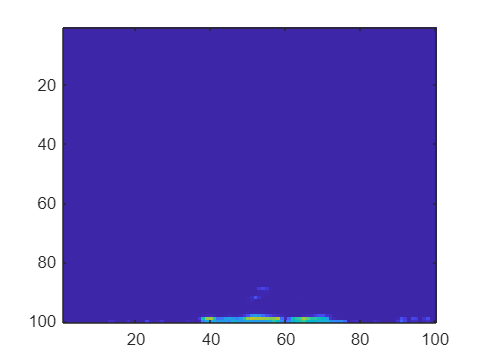



grayData = grayData(:, 3 : end);

subject_train = zeros(numExamples,1);
subject_train(1:7) = 1; % 1 = Ellie
subject_train(8:14) = 2; % 2 = Matthew
subject_train(15:21) = 3; % 3 = Xavier

image(smol(:,:,1))

% Get list of all files in the dataset directory
files = dir('TestDataset/*');

% Connor's voice <3

grayTest = zeros(10000, 3);

% Loop through each file
for i = 1:length(files)
    % Skip . and .. directory entries
    if ~files(i).isdir
        % Get the full file name
        fileName = fullfile('TestDataset', files(i).name);
        testData = imread(fileName);
        smolTest = imresize(testData, [100,100]); % Make the image smaller, so code doesnt explode
        
        gray = rgb2gray(smolTest);
        reshapeGray = reshape(gray, 10000,1);
        % Now you can process each file
        % For example, to read and display the filename:
        grayTest(:,i) = reshapeGray;
        disp(fileName);
        
        % Add your file processing code here
    end
end

TestDataset\EllieC.png
TestDataset\MatthewC.png
TestDataset\XavierC.png



grayTest = grayTest(:, 3 : end); % Deletes two blank columns

subject_test = [1 ; 2 ; 3];

save('SoundTrain.mat', 'grayData', 'subject_train')
save('SoundTest.mat', 'grayTest', 'subject_test')

